# Discrete Fourier Transform

The discrete Fourier transform, or DFT, is the primary tool of digital signal processing. The foundation of the product is the fast Fourier transform (FFT), a method for computing the DFT with reduced execution time. Many of the toolbox functions (including Z-domain frequency response, spectrum and cepstrum analysis, and some filter design and implementation functions) incorporate the FFT.

The MATLAB® environnement provides the functions *fft *and *ifft * to compute the discrete Fourier transform and its inverse, respectively. For the input sequence *x* and its transformed version *X *(the discrete-time Fourier transform at equally spaced frequencies around the unit circle), the two functions implement the relationships : 


$$X\left(k+1\right)=\sum_{n=0}^{N-1} x\left(n+1\right)W_N^{\mathit{kn}}$$


and 


$$x\left(n+1\right)=\frac{1}{N}\sum_{n=0}^{N-1} X\left(k+1\right)W_N^{-\mathit{kn}}$$


In these equations, the series of subscripts begin with 1 instead of 0 because of the MATLAB vector indexing scheme, and  $W_N =e^{-\mathrm{j2}\pi /N}$ .

**Note **The MATLAB convention is to use a negative *j* for the *fft *function. This is an engineering convention; pyhsics and pure mathematics typically use a positive *j*.

*fft, *with a single input argument, *x*, computes the DFT of the input vector or matrix. If x is vector, *fft *conputes the DFT of the vector; if *x* vector is a rectangular array, *fft * computes the DFT of each array column.

For example, create a time vector and signal :

clear
clear                                  % Clear all data stored in variables
Am = 1;                                % 1V Amplitude     
samplingFrequency = 48000;             % 48 KHz
f0 = 20e+3;                            % 20 KHz
f1 = 10e+3;                            % 10 KHz
duration = (127/samplingFrequency);    % ~ 2.6 ms 
t = 0:1/samplingFrequency:duration;    % Time Vector

sinusPulse = Am*sin(2*pi*f0*t) + Am/2*sin(2*pi*f1*t);
noisySinus_3dB = awgn(sinusPulse,3);       % Add noise to sinusPulse with SNR = 3 dB

Figure below shows sinusPulse and its noisy version :

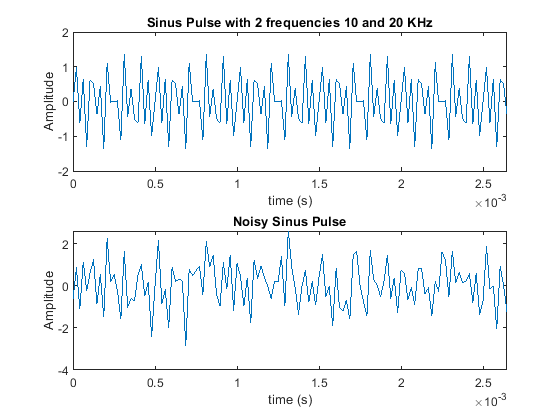

subplot(2,1,1)
plot(t,sinusPulse)
xlim([0 max(t)])
title('Sinus Pulse with 2 frequencies 10 and 20 KHz')
ylabel('Amplitude')
xlabel('time (s)')
subplot(2,1,2)
plot(t,noisySinus_3dB)
xlim([0 max(t)])
title('Noisy Sinus Pulse')
ylabel('Amplitude')
xlabel('time (s)')

Compute the DFT of the *noisySinus *and the magnitude of its DFT.

noisySinus_FFT = fft(noisySinus_3dB);       % Compute the DFT
magnitude = abs(noisySinus_FFT);            % Magnitude

Calculate the frequency vector and plot the single-sided amplitude spectrum.

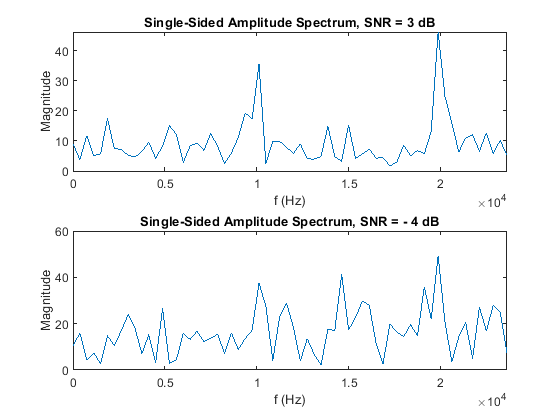

f = (0:length(noisySinus_3dB)/2-1)*samplingFrequency/length(noisySinus_3dB);    
% Frequency Vector
magnitude_Single_Sided  = magnitude(1:round(length(noisySinus_3dB)/2));

figure
subplot(2,1,1)
plot(f,magnitude_Single_Sided)
title('Single-Sided Amplitude Spectrum, SNR = 3 dB')
xlabel('f (Hz)')
ylabel('Magnitude')
xlim([0 max(f)])


noisySinus_4dB = awgn(sinusPulse,-4);            % Add noise with snr = -4 dB
magnitude_4db = abs(fft(noisySinus_4dB));       % Compute the DFT and Magnitude

magnitude_4db_S_S = magnitude_4db(1:round(length(noisySinus_4dB)/2));

subplot(2,1,2)
plot(f,magnitude_4db_S_S)
title('Single-Sided Amplitude Spectrum, SNR = - 4 dB')
xlabel('f (Hz)')
ylabel('Magnitude')
xlim([0 max(f)])

As we see in the figure above, the DFT capable to detect the frequencies *f0 = 20Khz* and *f1 = 10Khz* of the noisy signal with a snr >= 3 dB and can not detect f0 and f1 with a snr < 3 dB.

So we summarize this DFT article with a fundamental idea that proves the relationship between the DFT (Discrete Fourier Transform) and SNR (Signal-to-Noise Ratio) it is proportional with each other, so as we increase the SNR, the DFT detect the frequencies with high precision.

#### Referecens :

- [https://www.mathworks.com/help/signal/ug/discrete-fourier-transform.html](https://www.mathworks.com/help/signal/ug/discrete-fourier-transform.html)

- [https://en.wikipedia.org/wiki/Discrete_Fourier_transform](https://en.wikipedia.org/wiki/Discrete_Fourier_transform)